vmax = 12; %max velocity needed for shooting 10 m
s = 0.5; %stroke/length of the barrel [m]
m = 0.5; %mass of the carriage [kg]

t0 = 0;
t1 = 0.5;
dt = 0.000001;
t = [t0:dt:t1];
L = length(t);
v = zeros(1,L);
v(1) = 0.1;


a = zeros(1,L);
x = zeros(1,L);

P = 600;

tfinal = t1;

for i = 2 : L
    if x(i-1) >= s
        tfinal = t(i)
        ifinal = i - 1;
        break
    end
    a(i) = P / (m*v(i-1));
    v(i) = v(i-1) + a(i) * dt ;
    x(i) = x(i-1) + v(i)*dt;
end

tfinal = 0.0616

12 * 1.1

ans = 13.2000

v_ideal = v(ifinal)

v_ideal = 12.1644

a(2)*dt

ans = 0.0120

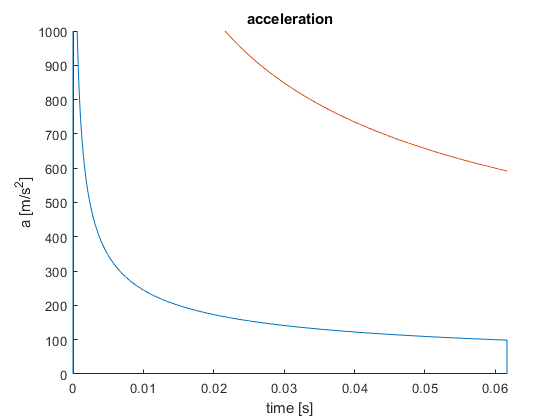

figure
clf
hold on
plot(t,a)
plot(t,6*(2*P*m./t).^(1/2))
xlim([0 tfinal])
ylim([0 1000])
title('acceleration')
xlabel('time [s]')
ylabel('a [m/s^2]')

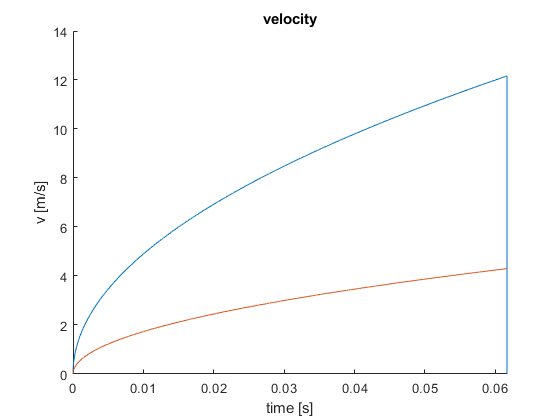

%ylim([0 100])
figure
clf
hold on
plot(t,v)
plot(t,sqrt(P*m*t))
xlim([0 tfinal])
title('velocity')
xlabel('time [s]')
ylabel('v [m/s]')

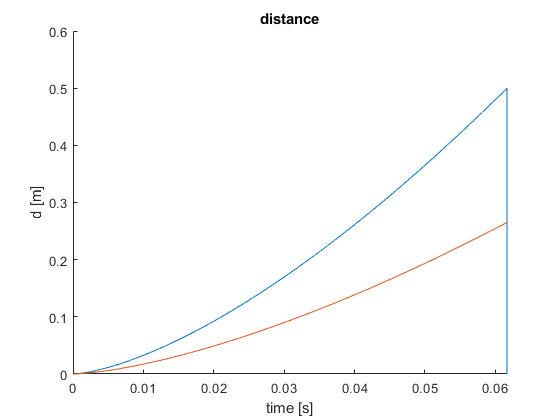


figure
clf
hold on 
plot(t,x)
plot(t,sqrt(P*m*t).*t)
xlim([0 tfinal])
title('distance')
xlabel('time [s]')
ylabel('d [m]')


t0 = 0;
t1 = 0.5;
dt = 0.00001;
t = [t0:dt:t1];
L = length(t);
v = zeros(1,L);
v(1) = 0.1;
mu = 0.8

mu = 0.8000


a = zeros(1,L);
x = zeros(1,L);

tfinal = t1;

for i = 2 : L
    if x(i-1) >= s
        tfinal = t(i)
        ifinal = i - 1;
        break
    end
    a(i) = ( P / v(i-1) - mu*v(i-1) )/m;
    v(i) = v(i-1) + a(i) * dt ;
    x(i) = x(i-1) + v(i)*dt;
end

tfinal = 0.0629

12 * 1.1

ans = 13.2000

v_frict = v(ifinal)

v_frict = 11.6928

(v_ideal - v_frict )/ v_ideal * 100

ans = 3.8775

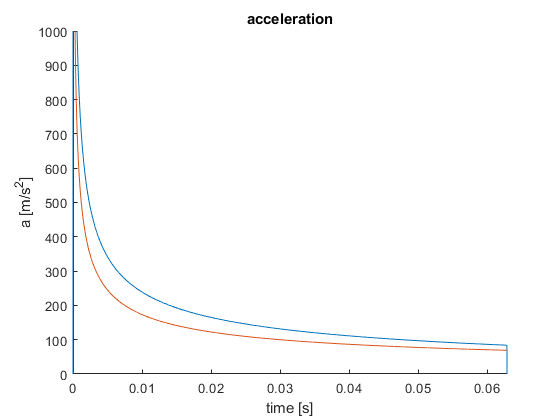


figure
clf
hold on
plot(t,a)
plot(t,sqrt(P*m./t))
xlim([0 tfinal])
ylim([0 1000])
title('acceleration')
xlabel('time [s]')
ylabel('a [m/s^2]')

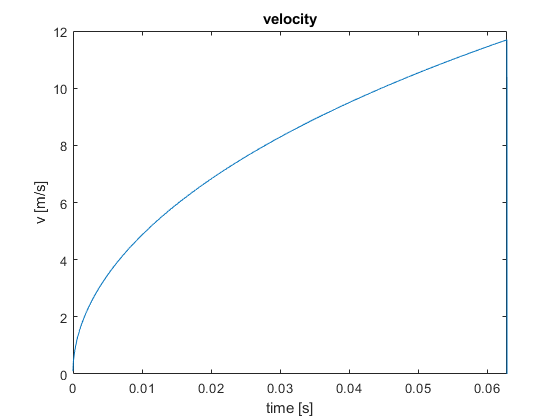

%ylim([0 100])
figure
hold on
clf
plot(t,v)
xlim([0 tfinal])
title('velocity')
xlabel('time [s]')
ylabel('v [m/s]')

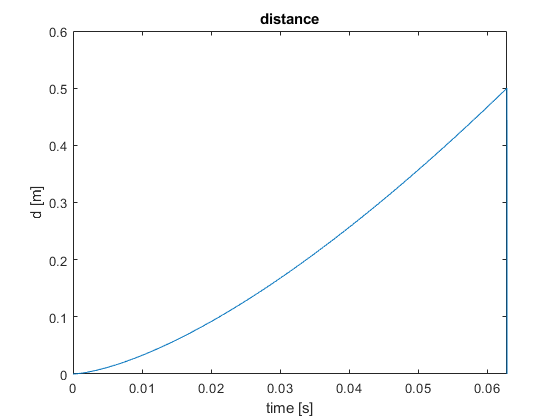


figure
clf
plot(t,x)
xlim([0 tfinal])
title('distance')
xlabel('time [s]')
ylabel('d [m]')

for j  = 1: 2
    for n = 1 : 10
        if j == 2
            P(n,j) = 2900/n + 50 * n^(1/6);
            mu = 0.8;
        else
            P(n,j) = 2900/n;
            mu = 0;
        end
        
        s = 0.1 * n;
        stroke(n) = s;
        t0 = 0;
        t1 = 0.5;
        dt = 0.00001;
        t = [t0:dt:t1];
        L = length(t);
        v = zeros(1,L);
        v(1) = 0.1;
        
        a = zeros(1,L);
        x = zeros(1,L);
        
        tfinal = t1;
        
        for i = 2 : L
            if x(i-1) >= s
                tfinal = t(i);
                ifinal = i - 1;
                break
            end
            a(i) = ( P(n) / v(i-1) - mu*v(i-1) )/m;
            v(i) = v(i-1) + a(i) * dt ;
            x(i) = x(i-1) + v(i)*dt;
        end
        finaltime(n,j) = tfinal;
        v_frict(n,j) = v(ifinal);
    end 
end 

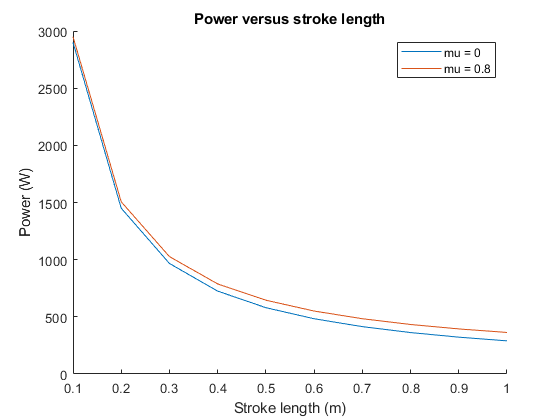

figure()
clf
hold on
plot(stroke,P(:,1))
plot(stroke,P(:,2))
title('Power versus stroke length')
xlabel('Stroke length (m)')
ylabel('Power (W)')
legend('mu = 0','mu = 0.8')

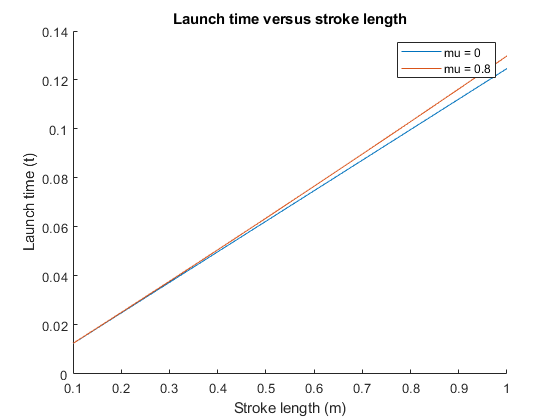

figure()
clf
hold on
plot(stroke,finaltime(:,1))
plot(stroke,finaltime(:,2))
legend('mu = 0' ,'mu = 0.8')
title('Launch time versus stroke length')
xlabel('Stroke length (m)')
ylabel('Launch time (t)')